% -- SPECTRAL PREPROCESSING WORKSTATION -----------------------------------
% Written by Cristian Ciobanu
%
% EDITED^2
%
% This is a workstation for preprocessing and analyzing Raman spectra.

close all;
clear;
clc; 
format long;

% -- GLOBAL INTERMEDIATE PREPROCESSED SPECTRA -----------------------------
% global csr sgf MSC SNV bgr bge hqt nrm avg hqr mdn craynum 

% -- GLOBAL PREPROCESSING SETTINGS ----------------------------------------
global avgNum sgfOrder sgfWindow snipOrder snipWindow
global threshold1 threshold2 remType range NISTspectrum

% cosmic ray removal settings
threshold1 = 6;
threshold2 = 1;
range = 1;
remType = 1;

% smoothing and averaging settings
sgfOrder = 2;
sgfWindow = 11;
avgNum = 15;
snipWindow = 111;
snipOrder = 2;

% -- PREPROCESSING OPTIONS ------------------------------- 6,1,11,10,8,2,5,6,7
% 1 - Cosmic Ray Removal         2 - Savitzky-Golay Smoothing
% 3 - MSC Correction             4 - SNV Correction
% 5 - Background Removal         6 - Outlier Removal
% 7 - Normalization              8 - Shuffle Averaging
% 9 - Median                     10 - Shift correction
% 11 - NIST correction

global standardSamples std_int shifts corr_shifts crnt info

% Reading in Silicon and Polystyrene data from separate collection dates

data_path = "/Users/haydnflemming/Desktop/LLAMPE - Research Project/Data/2024-07-05/";


% Determine the number of metadata rows to skip
numMetadataRows = 21; % Adjust this based on your inspection

file_name = "Growth(20x,495mW,BF)_2000_50_2024-07-05-16.24.47.267.csv";
file_path = data_path+file_name;
growth_495 = csvread(file_path, numMetadataRows, 0);

file_name = "Growth(20x,395mW,BF)_2000_50_2024-07-05-16.59.30.540.csv";
file_path = strcat(data_path,file_name);
growth_395 = csvread(file_path, numMetadataRows, 0);

file_name = "Growth(20x,295mW,BF)_2500_50_2024-07-05-17.09.51.890.csv";
file_path = strcat(data_path,file_name);
growth_295 = csvread(file_path, numMetadataRows, 0);

file_name = "Growth(20x,195mW,BF)_4000_50_2024-07-05-17.18.25.373.csv";
file_path = strcat(data_path,file_name);
growth_195 = csvread(file_path, numMetadataRows, 0);

file_name = "Growth(20x,95mW,BF)_4500_50_2024-07-05-17.29.04.300.csv";
file_path = strcat(data_path,file_name);
growth_95 = csvread(file_path, numMetadataRows, 0);

nist1 = readmatrix('Data/NIST_0823_120523_2023-05-12-08.23.54.csv');
NISTspectrum = [growth_95(1, 1:3101) ; nist1(23:end, :)];

file_name = "Polystyrene(20x,495mW)_50_100_2024-07-05-15.52.14.927.csv";
file_path = strcat(data_path,file_name);
poly1 = csvread(file_path, numMetadataRows, 0);
poly = mean(poly1(2:end,:));

file_name = "Silicon(20x,495mW)_180_100_2024-07-05-15.47.14.307.csv";
file_path = strcat(data_path,file_name);
Si1 = csvread(file_path, numMetadataRows, 0);
Si = mean(Si1(2:end,:));

std_int = [poly1(1, :) ; poly ; Si];

% Configuring and plotting unprocessed data

wavenumber = growth_495(1,:);

% trimming standard sample data to these WN's
t1 = 500;
t2 = 1800;
wavenumber(:, wavenumber(1, :) <= t1) = [];
wavenumber(:, wavenumber(1, :) >= t2) = [];
growth_495(:, growth_495(1, :) <= t1) = [];
growth_495(:, growth_495(1, :) >= t2) = [];
growth_395(:, growth_395(1, :) <= t1) = [];
growth_395(:, growth_395(1, :) >= t2) = [];
growth_295(:, growth_295(1, :) <= t1) = [];
growth_295(:, growth_295(1, :) >= t2) = [];
growth_195(:, growth_195(1, :) <= t1) = [];
growth_195(:, growth_195(1, :) >= t2) = [];
growth_95(:, growth_95(1, :) <= t1) = [];
growth_95(:, growth_95(1, :) >= t2) = [];

shifts = wavenumber;

wavelengths = 1 ./ (1/785 - wavenumber/1e7);

grow495 = growth_495(2:end, :);
grow395 = growth_395(2:end, :);
grow295 = growth_295(2:end, :);
grow195 = growth_195(2:end, :);
grow95 = growth_95(2:end, :);

std_int(:, std_int(1, :) <= t1) = [];
std_int(:, std_int(1, :) >= t2) = [];
std_int(1, :) = [];
standardSamples = ["Polystyrene" ; "Silicon"];

NISTspectrum(:, NISTspectrum(1, :) <= t1) = [];
NISTspectrum(:, NISTspectrum(1, :) >= t2) = [];
NISTspectrum(1, :) = [];

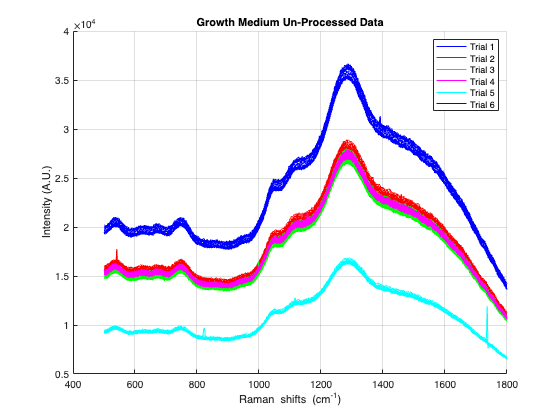

% Plotting unprocessed data

figure;
hold on;
grid on;
plot(wavenumber, grow495(1,:), '-b');
plot(wavenumber, grow395(1,:), '-r');
plot(wavenumber, grow295(1,:), '-g');
plot(wavenumber, grow195(1,:), '-m');
plot(wavenumber, grow95(1,:), '-c');
plot(wavenumber, grow495(2:end,:), '-b');
plot(wavenumber, grow395(2:end,:), '-r');
plot(wavenumber, grow295(2:end,:), '-g');
plot(wavenumber, grow195(2:end,:), '-m');
plot(wavenumber, grow95(2:end,:), '-c');
xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
title('Growth Medium Un-Processed Data');
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6');
hold off;

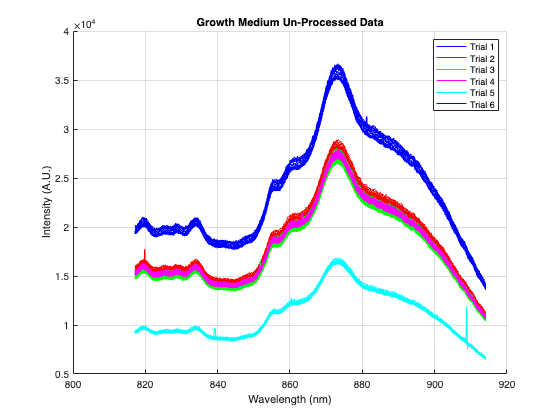

figure;
hold on;
grid on;
plot(wavelengths, grow495(1,:), '-b');
plot(wavelengths, grow395(1,:), '-r');
plot(wavelengths, grow295(1,:), '-g');
plot(wavelengths, grow195(1,:), '-m');
plot(wavelengths, grow95(1,:), '-c');
plot(wavelengths, grow495(2:end,:), '-b');
plot(wavelengths, grow395(2:end,:), '-r');
plot(wavelengths, grow295(2:end,:), '-g');
plot(wavelengths, grow195(2:end,:), '-m');
plot(wavelengths, grow95(2:end,:), '-c');
xlabel('Wavelength (nm)');
ylabel('Intensity (A.U.)');
title('Growth Medium Un-Processed Data');
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6');
hold off;

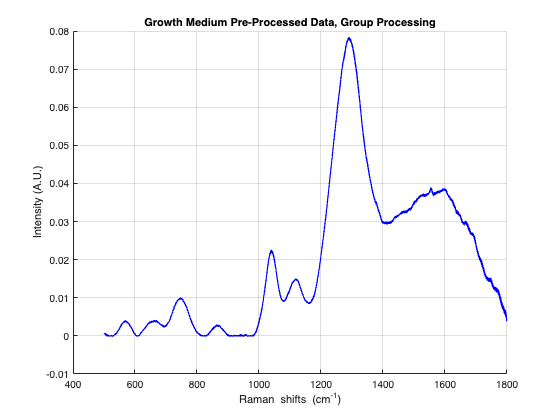

% Preprocessing the data

pro_grow495 = apply(grow495, [6,1,10,11,8,2,5,6,7]);
pro_grow395 = apply(grow395, [6,1,10,11,8,2,5,6,7]);
pro_grow295 = apply(grow295, [6,1,10,11,8,2,5,6,7]);
pro_grow195 = apply(grow195, [6,1,10,11,8,2,5,6,7]);
pro_grow95 = apply(grow95, [6,1,10,11,8,2,5,6,7]);

% Checking for processing full dataset at once vs individual

grow = [grow495;grow395;grow295;grow195;grow95];
pro_grow = apply(grow, [6,1,10,11,8,2,5,6,7]);

% Plotting pre-processed data

figure;
hold on;
grid on;
plot(wavenumber, pro_grow, '-b');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
title('Growth Medium Pre-Processed Data, Group Processing');
hold off;

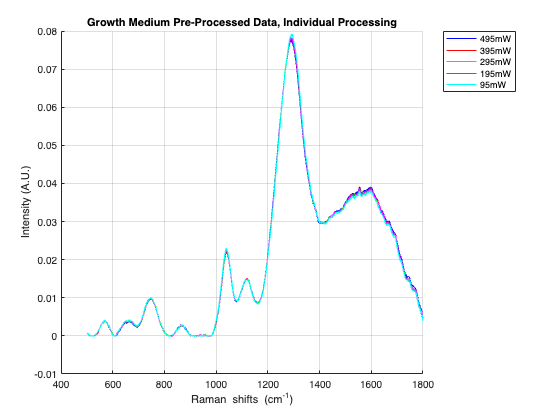

figure;
hold on;
grid on;
plot(wavenumber, pro_grow495(1,:), '-b');
plot(wavenumber, pro_grow395(1,:), '-r');
plot(wavenumber, pro_grow295(1,:), '-g');
plot(wavenumber, pro_grow195(1,:), '-m');
plot(wavenumber, pro_grow95(1,:), '-c');
plot(wavenumber, pro_grow495(2:end,:), '-b');
plot(wavenumber, pro_grow395(2:end,:), '-r');
plot(wavenumber, pro_grow295(2:end,:), '-g');
plot(wavenumber, pro_grow195(2:end,:), '-m');
plot(wavenumber, pro_grow95(2:end,:), '-c');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
title('Growth Medium Pre-Processed Data, Individual Processing');
legend('495mW','395mW','295mW','195mW','95mW', 'Location', 'northeastoutside');
hold off;

% Data for 1290 cm^-1 peak
Trial1 = pro_grow495(:, 790);
Trial2 = pro_grow395(:, 790);
Trial3 = pro_grow295(:, 790);
Trial4 = pro_grow195(:, 790);
Trial5 = pro_grow95(:, 790);

% Calculate means
av_Trial1 = mean(Trial1);
av_Trial2 = mean(Trial2);
av_Trial3 = mean(Trial3);
av_Trial4 = mean(Trial4);
av_Trial5 = mean(Trial5);

% Calculate standard deviations
std_Trial1 = std(Trial1);
std_Trial2 = std(Trial2);
std_Trial3 = std(Trial3);
std_Trial4 = std(Trial4);
std_Trial5 = std(Trial5);

% Number of spectra in each collection
n_Trial1 = size(Trial1, 1);
n_Trial2 = size(Trial2, 1);
n_Trial3 = size(Trial3, 1);
n_Trial4 = size(Trial4, 1);
n_Trial5 = size(Trial5, 1);

% Perform t-tests between pairs
[t_Trial1_Trial2, p_Trial1_Trial2, df_Trial1_Trial2] = perform_ttest(av_Trial1, av_Trial2, std_Trial1, std_Trial2, n_Trial1, n_Trial2);
[t_Trial1_Trial3, p_Trial1_Trial3, df_Trial1_Trial3] = perform_ttest(av_Trial1, av_Trial3, std_Trial1, std_Trial3, n_Trial1, n_Trial3);
[t_Trial1_Trial4, p_Trial1_Trial4, df_Trial1_Trial4] = perform_ttest(av_Trial1, av_Trial4, std_Trial1, std_Trial4, n_Trial1, n_Trial4);
[t_Trial1_Trial5, p_Trial1_Trial5, df_Trial1_Trial5] = perform_ttest(av_Trial1, av_Trial5, std_Trial1, std_Trial5, n_Trial1, n_Trial5);
[t_Trial2_Trial3, p_Trial2_Trial3, df_Trial2_Trial3] = perform_ttest(av_Trial2, av_Trial3, std_Trial2, std_Trial3, n_Trial2, n_Trial3);
[t_Trial2_Trial4, p_Trial2_Trial4, df_Trial2_Trial4] = perform_ttest(av_Trial2, av_Trial4, std_Trial2, std_Trial4, n_Trial2, n_Trial4);
[t_Trial2_Trial5, p_Trial2_Trial5, df_Trial2_Trial5] = perform_ttest(av_Trial2, av_Trial5, std_Trial2, std_Trial5, n_Trial2, n_Trial5);
[t_Trial3_Trial4, p_Trial3_Trial4, df_Trial3_Trial4] = perform_ttest(av_Trial3, av_Trial4, std_Trial3, std_Trial4, n_Trial3, n_Trial4);
[t_Trial3_Trial5, p_Trial3_Trial5, df_Trial3_Trial5] = perform_ttest(av_Trial3, av_Trial5, std_Trial3, std_Trial5, n_Trial3, n_Trial5);
[t_Trial4_Trial5, p_Trial4_Trial5, df_Trial4_Trial5] = perform_ttest(av_Trial4, av_Trial5, std_Trial4, std_Trial5, n_Trial4, n_Trial5);

% Display results
fprintf('t-test and p values for pairwise comparisons at 417 cm^-1 peak:\n');

t-test and p values for pairwise comparisons at 417 cm^-1 peak:


fprintf('Trial 1 vs Trial 2: t = %.4f, p = %.4f, df = %.4f\n', t_Trial1_Trial2, p_Trial1_Trial2, df_Trial1_Trial2);

Trial 1 vs Trial 2: t = -6.2286, p = 0.0065, df = 3.2675


fprintf('Trial 1 vs Trial 3: t = %.4f, p = %.4f, df = %.4f\n', t_Trial1_Trial3, p_Trial1_Trial3, df_Trial1_Trial3);

Trial 1 vs Trial 3: t = -8.2821, p = 0.0086, df = 2.3566


fprintf('Trial 1 vs Trial 4: t = %.4f, p = %.4f, df = %.4f\n', t_Trial1_Trial4, p_Trial1_Trial4, df_Trial1_Trial4);

Trial 1 vs Trial 4: t = -3.0484, p = 0.0689, df = 2.5365


fprintf('Trial 1 vs Trial 5: t = %.4f, p = %.4f, df = %.4f\n', t_Trial1_Trial5, p_Trial1_Trial5, df_Trial1_Trial5);

Trial 1 vs Trial 5: t = -10.0978, p = 0.0016, df = 3.1772


fprintf('Trial 2 vs Trial 3: t = %.4f, p = %.4f, df = %.4f\n', t_Trial2_Trial3, p_Trial2_Trial3, df_Trial2_Trial3);

Trial 2 vs Trial 3: t = -2.0781, p = 0.1309, df = 2.9462


fprintf('Trial 2 vs Trial 4: t = %.4f, p = %.4f, df = %.4f\n', t_Trial2_Trial4, p_Trial2_Trial4, df_Trial2_Trial4);

Trial 2 vs Trial 4: t = -0.5544, p = 0.6306, df = 2.1948


fprintf('Trial 2 vs Trial 5: t = %.4f, p = %.4f, df = %.4f\n', t_Trial2_Trial5, p_Trial2_Trial5, df_Trial2_Trial5);

Trial 2 vs Trial 5: t = -7.0850, p = 0.0108, df = 2.4590


fprintf('Trial 3 vs Trial 4: t = %.4f, p = %.4f, df = %.4f\n', t_Trial3_Trial4, p_Trial3_Trial4, df_Trial3_Trial4);

Trial 3 vs Trial 4: t = -0.0538, p = 0.9619, df = 2.0491


fprintf('Trial 3 vs Trial 5: t = %.4f, p = %.4f, df = %.4f\n', t_Trial3_Trial5, p_Trial3_Trial5, df_Trial3_Trial5);

Trial 3 vs Trial 5: t = -6.5970, p = 0.0192, df = 2.1169


fprintf('Trial 4 vs Trial 5: t = %.4f, p = %.4f, df = %.4f\n', t_Trial4_Trial5, p_Trial4_Trial5, df_Trial4_Trial5);

Trial 4 vs Trial 5: t = -3.5936, p = 0.0297, df = 3.4274


function [t_val, p_val, df] = perform_ttest(av1, av2, std1, std2, n1, n2)
    t_val = (av1 - av2) / sqrt((std1^2 / n1) + (std2^2 / n2));
    df = ((std1^2 / n1) + (std2^2 / n2))^2 / ...
         (((std1^2 / n1)^2 / (n1 - 1)) + ((std2^2 / n2)^2 / (n2 - 1)));
    p_val = 2 * (1 - tcdf(abs(t_val), df));
end

function [all, train, test] = prepSet(data, donor, doses, ser, preprocessing)
    all = 0;
    global crnt info
    
    if donor == -1
        donor = unique(data(:,1));
    end

    if doses == -1
        doses = unique(data(:,2))';
        if ismember(999,doses)
            doses = doses(1:end-1);
        end
    end
    
    compiled_to_shuffle = cell(size(doses));
    
    for i = 1:size(donor,2)
        for j = 1:size(doses,2)
            [info, crnt] = dataPicker(data, donor(i), doses(j), ser);

            [crnt, removed] = apply(crnt, preprocessing);
            
            if ismember(8,preprocessing) || ismember(9,preprocessing)
                numRows = ones(size(crnt,1),1);
                info = [donor(i)*numRows doses(j)*numRows 999*numRows];
            else
                for k = 1:size(removed,2)
                    info(removed{k},:) = [];
                end
            end
            
            if all == 0
                all = [info crnt];
            else
                all = [all; info crnt];
            end
            
            if compiled_to_shuffle{j} == 0
                compiled_to_shuffle{j} = [info crnt];
            else
                compiled_to_shuffle{j} = [compiled_to_shuffle{j}; info crnt];
            end
        end
    end
    
    all(:,2) = all(:,2) + 1;
    [train, test] = combine(compiled_to_shuffle);
    train(:,2) = train(:,2) + 1;
    test(:,2) = test(:,2) + 1;
end

function [crnt, removed, corr_shifts] = apply(data, operations)
    global csr sgf MSC SNV bgr bge hqt nrm avg hqr mdn nistcorr NISTspectrum
    
    global avgNum sgfOrder sgfWindow snipOrder snipWindow

    global standardSamples std_int shifts corr_shifts

    global craynum range threshold1 threshold2 remType

    crnt = data;
    
    removed = {};
    
    for i = operations
        if i == 1
            % [crnt, ~, ~, craynum] = remCrays(crnt,1.5,range);
            [crnt, ~, ~, craynum] = CRremove(crnt, threshold1, threshold2, range, remType);
            csr = crnt;
        elseif i == 2
            crnt = sgolayfilt(crnt',sgfOrder,sgfWindow)';
            sgf = crnt;
        elseif i == 3
            [crnt, ~] = msc(crnt);
            MSC = crnt;
        elseif i == 4
            crnt = snv(crnt);
            SNV = crnt;
        elseif i == 5
            [crnt, bge, ~] = bgrem(crnt, snipWindow, 2, 15, snipOrder);
            bgr = crnt;
        elseif i == 6
            [crnt, hqr] = hqTest(crnt);
            removed{1,end+1} = hqr;
            hqt = crnt;
        elseif i == 7
            crnt = normr(crnt);
            nrm = crnt;
        elseif i == 8
            crnt = shuffle(crnt);
            crnt = averager(crnt, avgNum);
            avg = crnt;
        elseif i == 9
            crnt = median(crnt);                                                                    
            mdn = crnt;
       elseif i == 10
            [corr_shifts, crnt] = ramancorrect(shifts, std_int, standardSamples, crnt);
       elseif i == 11
            crnt = nistCorrect(crnt, NISTspectrum, shifts);
            nistcorr = crnt;
        end
    end
end




